# Analog Filters

## Theoretical introduction

Analog circuits

 
$$x(t) \rightarrow [circuit] \rightarrow y(t)$$
 

are described by differential & integral equations. After performing upon their inputs and outputs the Laplace transform and the continuous Fourier transform (the special case of the Laplace transform for $s=j2\pi f$), defined as, respectively:


$$X(s) = \int_{-\infty}^{\infty}{x(t)e^{-st}dt}, \qquad \qquad  X(f) = \int_{-\infty}^{\infty}{x(t)e^{-j2\pi ft} dt },$$


one obtains:


$$X(s) \rightarrow [circuit \; H(s)] \rightarrow Y(s),  \qquad \qquad  X(f) \rightarrow [circuit \; H(f)] \rightarrow Y(f),$$


and, finally, a circuit transfer function  and  a circuit frequency response:


$$H(s)=\frac{Y(s)}{X(s)}, \qquad \qquad H(f)=\frac{Y(f)}{X(f)}.$$
 

The circuit frequency response $H(f)$ gives us information what our circuit will do with input sinusoidal oscillation with frequeny $f$, and:

-  $|H(f)|$ - sinusoid gain,

-  $\angle H(f)$- sinusoid shift angle.

## RLC circuit as an example

Let's discuss the RLC circuit (R-resistor, L-induction coil, C-capacitor), presented in figure below, as an example.

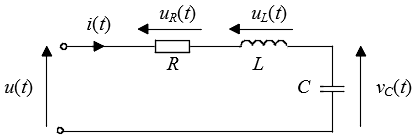

Its output and input voltages are equal:


$$u_{out}(t)=u_{C}(t)=\frac{1}{C}\int_{0}^{t}i(t)dt$$



$$u_{in}(t)=u_{R}(t) + u_{L}(t) + u_{C}(t) = Ri(t)+L \frac{di(t)}{dt}+\frac{1}{C}\int_{0}^{t}i(t)dt$$


After: 1) calculating the Laplace (Fourier) transform of both sides of the above equations, and 2) dividing the first equation by the second, one obtatains the circuit transfer function $H(s)$and the circuit frequency response $H(f)$, respectively:


$$H(s)=\frac{U_{out}(s)}{U_{out}(s)} = \frac{\frac{1}{sC}}{R+Ls+\frac{1}{sC}}=\frac{1}{LCs^2+RCs+1}, \qquad \qquad H(f)=\frac{1}{LC(j2\pi f)^2+RC(j2\pi f)+1},$$


which is a ratio of two polynomials of variable $s$ (or $j2\pi f$).  Circuit response to the Dirac delta function (impulse) $\delta(t)$is equal (for $t \geq 0$):


$$h(t)=Ae^{-\alpha t} \sin(\omega_1 t), \qquad \omega_0=\frac{1}{\sqrt{LC}}, \quad \xi=\frac{R/L}{2\omega_0}, \quad A=\frac{\omega_0}{\sqrt{1-\xi ^2}}, \quad \alpha=\xi \omega_0, \quad \omega_1=\omega_0 \sqrt{1-\xi ^2}.$$


**Matlab code**, given below, calculates the frequency response of the RLC circuit and simulates its impulse respone. Change values of R, L, C and observe changes of both circuit characteristics. Change frequency range of observation. Is the impulse response always oscillatory? $H(f)$ is the result of Fourier transform of $h(t)$.

clear all; close all;

R = 10;                   % resistance in ohms
L = 2*10^(-3);            % inductance in henrys
C = 5*10^(-6);            % capacitance in farads

w0  = 1/sqrt(L*C);        f0 = w0/(2*pi),    % undumped resonance frequency 

f0 = 1.5915e+03

ksi = (R/L)/(2*w0),                          % should be smaller than 1 

ksi = 0.2500

w1  = w0*sqrt(1-ksi^2);   f1 = w1/(2*pi),    % damped resonance frequency

f1 = 1.5410e+03

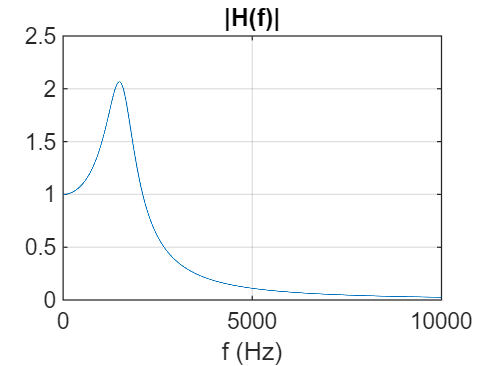

   
b = [ 1 ];                % coeffs of nominator polynomial
a = [ L*C, R*C, 1 ];      % coeffs of denominator polynomial (the highest order first)

% Frequency response
  f = 0 : 1 : 10000;              % frequency range of interest
  w = 2*pi*f; s = j*w;            % radial frequency, Laplace transform variable 
  H = polyval(b,s)./polyval(a,s); % frequency response H(f) = H(s=j*2*pi*f)
% H = freqs(b,a,2*pi*f);          % Matlab function doing the same
% Figures
  figure; plot(f,abs(H)); xlabel('f (Hz)'); title('|H(f)|'); grid;

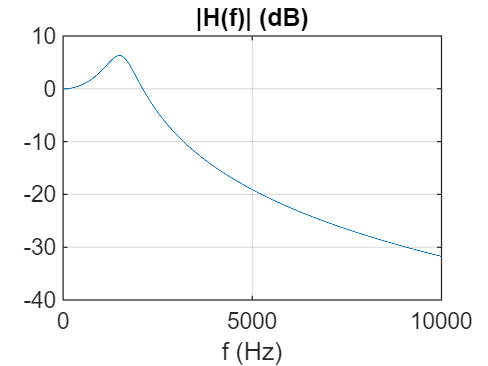

  figure; plot(f,20*log10(abs(H))); xlabel('f (Hz)'); title('|H(f)| (dB)'); grid;

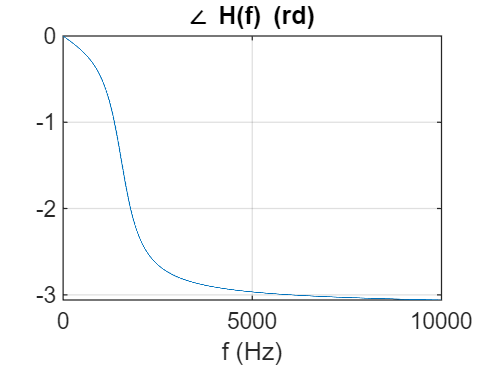

  figure; plot(f,angle(H)); xlabel('f (Hz)'); title('\angle H(f) (rd)'); grid;

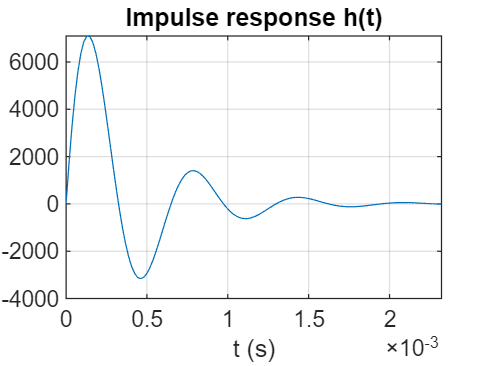

  [h,t] = impulse(tf(b,a));       % calculate circuit impulse response h(t)
  plot(t,h); xlabel('t (s)'); title('Impulse response h(t)'); grid;

## H(s) design by zeros & poles selection

In general, an analog circuit is defined by differential [input $x(t)$$\rightarrow$output $y(t)$] equation:


$${{b}_{0}}x(t)+{{b}_{1}}\frac{dx(t)}{dt}+...+{{b}_{M}}\frac{d{{x}^{M}}(t)}{d{{t}^{M}}}=y(t)+{{a}_{1}}\frac{dy(t)}{dt}+...+{{a}_{N}}\frac{d{{y}^{N}}(t)}{d{{t}^{N}}}$$


After performing the Laplace transform (LT) of its both sides and exploiting the LT feature $L \left( \frac{d{{x}^{m}}(t)}{d{{t}^{m}}} \right)={{s}^{m}}X(s)$, one obtains:

 $H(s)=\frac{Y(s)}{X(s)}=\frac{{{b}_{0}}+{{b}_{1}}{{s}^{1}}+{{b}_{2}}{{s}^{2}}+...+{{b}_{M}}{{s}^{M}}}{1+{{a}_{1}}{{s}^{1}}+{{a}_{2}}{{s}^{2}}+...+{{a}_{N}}{{s}^{N}}} = \frac{{{b}_{M}}\cdot (s-{{z}_{1}})(s-{{z}_{1}^{*}})\cdot ...\cdot (s-{{z}_{M/2}})(s-{{z}_{M/2}^{*}})}{{{a}_{N}}\cdot (s-{{p}_{1}})(s-{{p}_{1}^{*}})\cdot ...\cdot (s-{{p}_{N/2}})(s-{{p}_{N/2}^{*}})}$.

Instead of "design" of values of polynomial coefficients $\{ b_k, a_k\}$, ensuring the required $|H(f)|=|H(s)|_{s=j2\pi f}$, we can "design" values of polynomial roots $\{  z_k, p_k \}$, what is more easier:

- setting $H(s)$ zero $z_k=j2\pi f_k$ - removes sinusoid with frequency $f_k$  from our circuit output,

- setting $H(s)$ pole $p_k = -\varepsilon + j2\pi f_k$ - amplifies sinusoid with frequency $f_k$ on our circuit output, stronger for smaller values of positive constant $\varepsilon$.

**Analyze the Matlab code**. Run it, observe figures. Add one more frequency to reject and one more - to amplify. Try to design an analog filter having flat passing band (linear gain 1 or decibel gain 0 dB) in some frequency interval:

- Low-Pass (LP): $[0,f_{stop}]$ Hz,

- High-Pass (HP): $[f_{start}, +\infty]$ Hz,

- Band-Pass (BP):  $[f_{start}, f_{stop}]$ Hz,

- Band-Stop (BS):  $[0, f_{stop}]  \;\; \text{and} \;\;  [f_{stop}, +\infty]$ Hz.

 Attennuate as much as possible all frequencies lying outside the passband.    

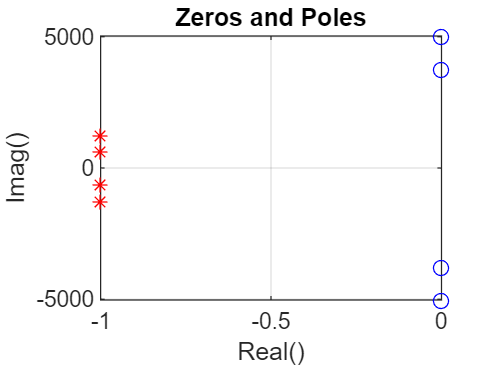

% Design of polynomials of analog circuit/filter transfer function H(z)
  if(0)  % choosing polynomial coefficients [b,a] - nobody knows what filter will result
     b = [3,2];                      % [ b1, b0 ]
     a = [4,3,2,1];                  % [ a3, a2, a1, a0=1]
     z = roots(b); p = roots(a);     % [b,a] --> [z,p]
  else   % choosing polynomial roots [z,p] - our conscious decision
     gain = 0.001;
     z = j*2*pi*[ 600,800 ];         z = [z conj(z)];    % removing frequencies 600 and 800 Hz 
     p = [-1,-1] + j*2*pi*[100,200]; p = [p conj(p)];    % amplifying frequencies 100 and 200 Hz
     b = gain*poly(z);  a = poly(p);                     % [z,p] --> [b,a]  
  end
  figure; plot(real(z),imag(z),'bo', real(p),imag(p),'r*'); grid;
  title('Zeros and Poles'); xlabel('Real()'); ylabel('Imag()');

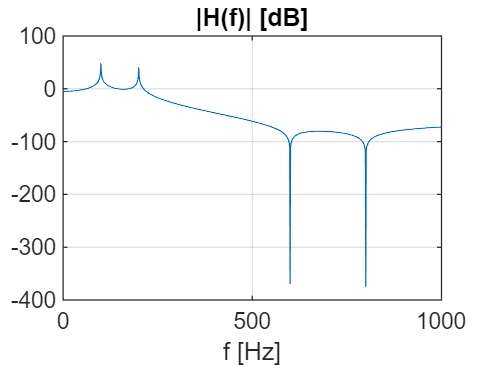

% Verification of the obtained filter frequency response H(f): gain and phase shift as a function of freq
  f = 0:1:1000;                      % frequencies of interest in hertz
  H = freqs(b,a,2*pi*f);             % filter frequency response H(f) via Matlab function 
  figure; plot(f,20*log10(abs(H))); xlabel('f [Hz]'); title('|H(f)| [dB]'); grid;

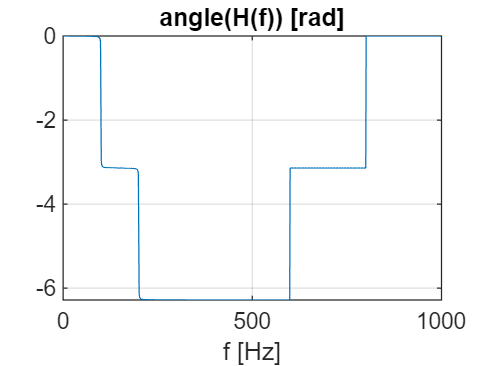

  figure; plot(f,unwrap(angle(H))); xlabel('f [Hz]'); title('angle(H(f)) [rad]'); grid; 

## Butterworth low-pass prototype filter

Butterwoth proposed a low-pass $[0,f_{stop}]$ filter having $H(s)$ of the form:


$$H(s)=\frac{(-p_1)(-p_2)...(-p_N)}{(s-p_1)(s-p_2)...(s-p_N)}, \quad p_k=(2\pi f_{stop}) e^{j \varphi_k}, \quad \varphi_k = \frac{\pi}{2} + \frac{\Delta \varphi}{2} + \Delta \varphi  \cdot (k-1), \quad \Delta \varphi=\frac{\pi}{N}, \quad k=1,2,...,N.$$
 

with poles lying on the circle with the radius $R=\omega_{stop}=2\pi f_{stop}$, but only in the left half-plane of variable $s$. Value of $N$ decides about the sharpness of the filter transition from passband to stopband ($|H(f)|$ decreases $-20N$ decibels when frequency is increased 10 times).

**Analyze the Matlab code**. Add calculation and plotting of $|H(f)|$ to this program.

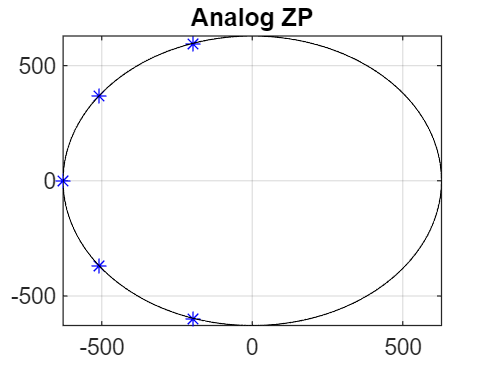

% Low-pass and high-pass analog Butterworth filters
N = 5;                                   % number of TF poles
f0 = 100;                                % cut-off frequency of low-pass filter
alpha = pi/N;                            % angle of one ``piece of cake''
beta  = pi/2 + alpha/2 + alpha*(0:N-1);  % angles of all poles of H(s)
R = 2*pi*f0;                             % circle radius
p = R*exp(j*beta);                       % poles placed on the circle, in left half-plane only
z = []; gain = prod(-p);                 % LOW-PASS: TF zeros are not used, gain
%z = zeros(1,N); gain = 1;               % HIGH-PASS: N TF zeros in zero, gain
b = gain*poly(z); a=poly(p);             % [z,p] --> [b,a]
b = real(b);      a=real(a);             %
H = freqs(b,a,2*pi*f);                   % Matlab function
fi=0:pi/1000:2*pi; c=R*cos(fi); s=R*sin(fi);
figure; plot(real(z),imag(z),'ro',real(p),imag(p),'b*',c,s,'k-'); grid; title('Analog ZP');

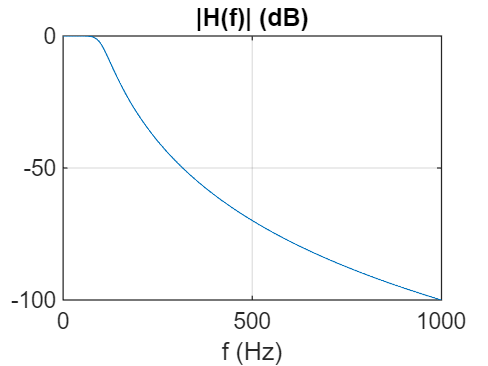

figure; plot(f,20*log10(abs(H))); xlabel('f (Hz)'); title('|H(f)| (dB)'); grid;

## Other Butterworth filters via frequency transformations

Procedure for obtaining other Butterworth filter types, e.g. high-pass, band-pass and band-stop, is as follows:

- design a low-pass Butterworth prototype filter for $\omega_{stop}=1$ choosing sufficiently high value of $N$ (deciding about filter frequency sharpness),

- transform it in frequency to another filter using known substitution $s=\text{function}(s')$:


$$H_{LP}^{[0, \omega_0=1]}(s) \quad \rightarrow \quad \left[ s=\text{function}(s') \right] \quad \rightarrow \quad H_{LP,HP,BP,BS}^{[\omega_1,\omega_2]} (s').$$
 

In fact Chebyshev and Cauer filters, presented in the next section, have been also originally defined as low-pass, and has to be transformed in order to obtain other filter types.

Let's look deeper into a Low-Pass to Band-Pass transformation of the Butterwort filter. In the LP2BP frequency transformation the $s$-variable exchange equation is as follows:

$s=\frac{s{{'}^{2}}+\omega _{center}^{2}}{\Delta \omega \cdot s'}, \qquad \omega_{center}=\sqrt{\omega_{start} \cdot \omega_{stop}}, \qquad \Delta \omega = \omega_{stop}-\omega_{start}$. 

As a result each term $(s-z_k)$  (or $(s-p_k)$)  of low-pass $H(s)$ should be replaced by the term:

$\left( \frac{s{{'}^{2}}+\omega _{center}^{2}}{\Delta \omega \cdot s'} - z_k \right) = \frac{{{(s')}^{2}}-{{z}_{k}}\Delta \omega \cdot (s')+\omega _{0}^{2}}{\Delta \omega \cdot (s')}$,

giving as a result ratio of two polynomials with completely different coefficients. 

**Analyze the Matlab code**. Do some changes.

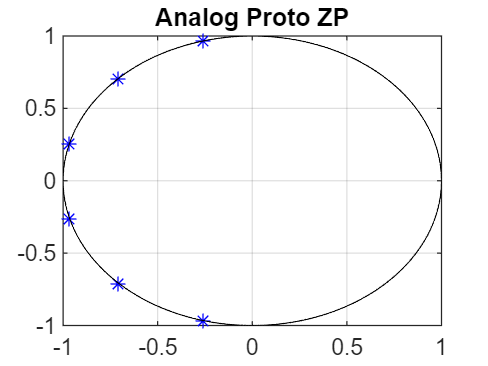

% Requirements
  N = 6;              % number of poles in H(s) of the analog low-pass prototype filter
  f0 = 100;           % for LowPass and HighPass
  f1 = 100; f2=200;   % for BandPass and BandStop
% Design of analog LowPass prototype filters for w0 = 1
  w = 0 : 0.01 : 10;                % radial frequencies of interest for the low-pass prototype
  [z,p,gain] = buttap(N);           % analog Butterwoth low-pass prototype filter (butt ap)
  b = gain*poly(z); a = poly(p);    % [z,p,gain] --> [b,a]     
  H = freqs(b,a,w);                 % filter frequency response using Matlab  
  fi=0:pi/1000:2*pi; c=cos(fi); s=sin(fi);
  figure; plot(real(z),imag(z),'ro',real(p),imag(p),'b*',c,s,'k-'); grid; title('Analog Proto ZP');

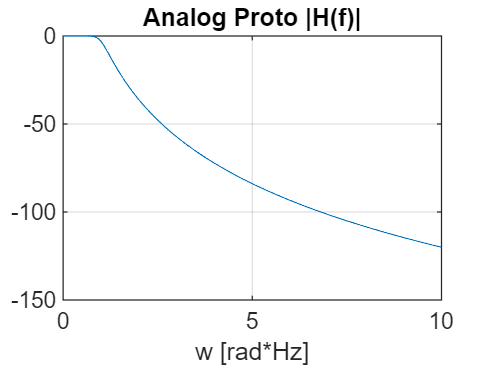

  figure; plot(w,20*log10(abs(H))); grid; xlabel('w [rad*Hz]'); title('Analog Proto |H(f)|'); 

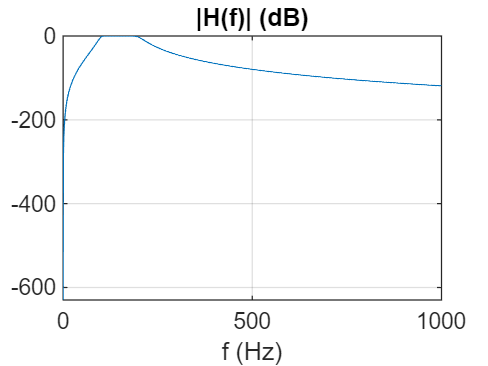

% Frequency transformation: Normalized (w0=1) LowPass --> DifferentPass
% Functions xx2yy from Signal Processing Toolbox (xx,yy = lp,hp,bp,bs)
% [b,a] = lp2lp(b,a,2*pi*f0);                         % LowPass to LowPass
% [b,a] = lp2hp(b,a,2*pi*f0);                         % LowPass to HighPass
  [b,a] = lp2bp(b,a,2*pi*sqrt(f1*f2),2*pi*(f2-f1));   % LowPass to BandPass
% [b,a] = lp2bs(b,a,2*pi*sqrt(f1*f2),2*pi*(f2-f1));   % LowPass to BandStop
  H = freqs(b,a,2*pi*f);                              % Matlab function
  figure; plot(f,20*log10(abs(H))); xlabel('f (Hz)'); title('|H(f)| (dB)'); grid;

##  Chebyshev and Cauer (elliptic) filters

Chebyshev I/II (1/2) and Cauer (elliptic) filters are alternatives to the Butterwoth filters. Magnitude frequency response of the Butterworth filter does not have oscillations in the passband (it is flat) and stopband (it is continuously decaying). This is  achieved at the price of low filter sharpness. Other filters allows oscillations:

- Chebyshev I - in the passband,

- Chebyshev Ii - in the stopband,

- Cauer (elliptic) - both, in the passband and stopband.

Filters with bigger oscillations are sharper. Now we will design analog filter coefficients `[b,a]` using the following Matlab functions: `butter(), cheby1(), cheby2(), ellip()`.  Shapes of their frequency responses $|H(f)|$ are compared in figure below. Note presence of oscillations and different filter sharpness. Note different behaviour of Chebyshev II filter (during its design beging of the stopband, not end of passband, is specified). 

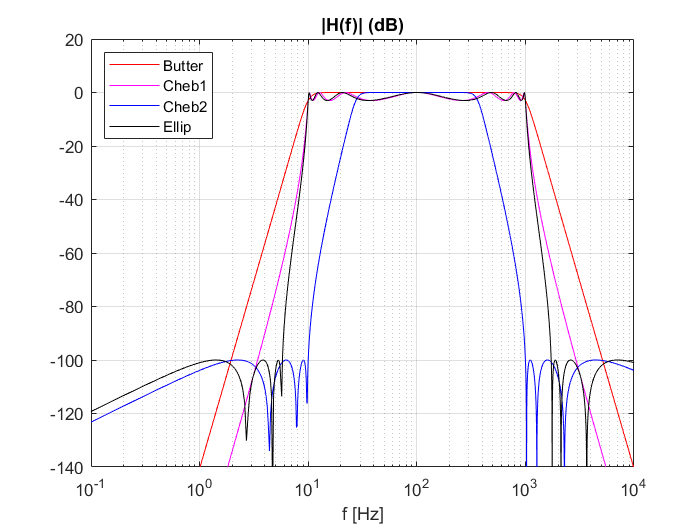

**Analyze the Matlab code**. Run, observe, modify. Try to obtained similar plots as above.

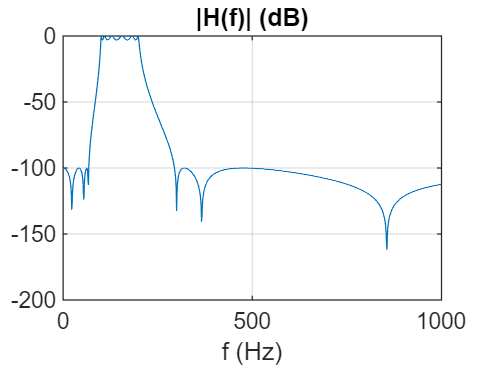

N = 6;                   % number of transfer function poles
f0=10;  f1=100;  f2=200; % frequencies in Hz [1/s]
Rp = 3; Rs = 100;        % allowed ripples in dB in the passband and stopband
% [b,a] = butter(N, 2*pi*f0, 'low','s');                    % Butt  LowPass 
% [b,a] = butter(N, 2*pi*f0, 'high','s');                   % Butt  HighPass
% [b,a] = butter(N, 2*pi*[f1,f2], 'stop', 's');             % Butt  BandStop
% [b,a] = butter(N, 2*pi*[f1,f2], 'bandpass', 's');         % Butt  BandPass
% [b,a] = cheby1(N, Rp, 2*pi*[f1,f2], 'bandpass', 's');     % Cheb1 BandPass
% [b,a] = cheby2(N, Rs, 2*pi*[f1,f2], 'bandpass', 's');     % Cheb2 BandPass
  [b,a] =  ellip(N, Rp, Rs,2*pi*[f1,f2], 'bandpass', 's');  % Ellip BandPass
H = freqs(b,a,2*pi*f);                   % Matlab function
figure; plot(f,20*log10(abs(H))); xlabel('f (Hz)'); title('|H(f)| (dB)'); grid;